# Dealing with Multi-Variable Systems: Identification and Analysis

This example shows how to deal with data with several input and output channels (MIMO data). Common operations, such as viewing the MIMO data, estimating and comparing models, and viewing the corresponding model responses are highlighted.

## The Data Set

We start by looking at the data set SteamEng.

datashaker_000_1 = readtable('sumitomorikodeadlinejan192018/no_shake_0.00mm.csv');

N = size(datashaker_000_1,1);
datashaker_000_1a =[datashaker_000_1 table(zeros(N,1), zeros(N,1), zeros(N,1), 'VariableNames',{'AccX_m_s2_';'AccY_m_s2_';'AccZ_m_s2_'})]; 

datashaker_350_1 = readtable('sumitomorikodeadlinejan192018/2post_shaker_3.50mm.csv');

datashaker_350_2 = readtable('sumitomorikodeadlinejan192018/2post_shaker_3.50mm th0.99_Jan11_2018.csv');


datashaker_750_2 = readtable('sumitomorikodeadlinejan192018/2post_shaker_7.50mm th0.99_Jan6_2018.csv');

datashaker_750_1 = readtable('sumitomorikodeadlinejan192018/2post_shaker_7.50mm.csv');

GS20_city_th99_1 = readtable('sumitomorikodeadlinejan192018/GS 20 min city th0.99 norm indiv_Jan6_2018.csv');

GS20_city_th99_2 = readtable('sumitomorikodeadlinejan192018/GS 20 min highway th0.99 norm indiv_Jan6_2018.csv');

GS20_city_acc_1 = readtable('sumitomorikodeadlinejan192018/GS_20min_city_withAcc_ec.csv');

GS20_city_acc_2 = readtable('sumitomorikodeadlinejan192018/GS_20min_highway_withAcc_ec.csv');

 clear XXW*;
 clear YYW*

for i=1:4:size(datashaker_350_2,1)-4 XXW350_2(floor(i/4+1),:) = [datashaker_350_2.wi1(i), datashaker_350_2.wi2(i),datashaker_350_2.wi3(i),datashaker_350_2.wi4(i), datashaker_350_2.wi1(i+1), datashaker_350_2.wi2(i+1),datashaker_350_2.wi3(i+1),datashaker_350_2.wi4(i+1), datashaker_350_2.wi1(i+2), datashaker_350_2.wi2(i+2),datashaker_350_2.wi3(i+2),datashaker_350_2.wi4(i+2), datashaker_350_2.wi1(i+3), datashaker_350_2.wi2(i+3),datashaker_350_2.wi3(i+3),datashaker_350_2.wi4(i+3),datashaker_350_2.candidateHeartRate_Bpm(i), datashaker_350_2.candidateHeartRate_Bpm(i+1),datashaker_350_2.candidateHeartRate_Bpm(i+2),datashaker_350_2.candidateHeartRate_Bpm(i+3) ] ; end;
 for i=1:4:size(datashaker_750_2,1)-4 ; XXW750_2(floor(i/4+1),:) = [datashaker_750_2.wi1(i), datashaker_750_2.wi2(i),datashaker_750_2.wi3(i),datashaker_750_2.wi4(i), datashaker_750_2.wi1(i+1), datashaker_750_2.wi2(i+1),datashaker_750_2.wi3(i+1),datashaker_750_2.wi4(i+1), datashaker_750_2.wi1(i+2), datashaker_750_2.wi2(i+2),datashaker_750_2.wi3(i+2),datashaker_750_2.wi4(i+2), datashaker_750_2.wi1(i+3), datashaker_750_2.wi2(i+3),datashaker_750_2.wi3(i+3),datashaker_750_2.wi4(i+3),datashaker_750_2.candidateHeartRate_Bpm(i),datashaker_750_2.candidateHeartRate_Bpm(i+1),datashaker_750_2.candidateHeartRate_Bpm(i+2),datashaker_750_2.candidateHeartRate_Bpm(i+3) ] ; end;
 for i=1:4:size(datashaker_350_2,1)-4 ; YYW350_2(floor(i/4+1),:) = [datashaker_350_2.ppgHeartRate_Bpm(i) ] ; end;
 for i=1:4:size(datashaker_750_2,1)-4 ; YYW750_2(floor(i/4)+1,:) = [datashaker_750_2.ppgHeartRate_Bpm(i)]; end;  

XXW=[XXW350_2;XXW750_2;];
YYW=[YYW350_2;YYW750_2];


 datashaker = [datashaker_000_1a;datashaker_350_1;datashaker_750_1];

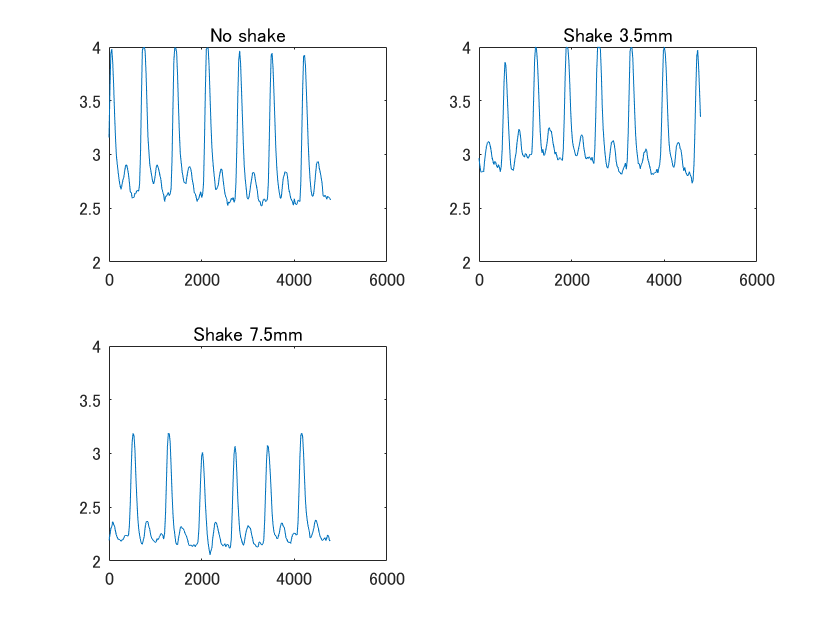

clf;
nn=0;
rows=2;cols=2;

tlim=60*4;

%Plot shaker response raw data
nn=nn+1;
subplot(rows,cols,nn);
plot(datashaker_000_1.Time_mS_(1:tlim,:),datashaker_000_1.ppg(1:tlim,:))
title("No shake")
axis([0 6000 2 4])

nn=nn+1;
subplot(rows,cols,nn);
plot(datashaker_350_1.Time_mS_(1:tlim,:),datashaker_350_1.ppg(1:tlim,:))
title("Shake 3.5mm")
axis([0 6000 2 4])

nn=nn+1;
subplot(rows,cols,nn);
plot(datashaker_750_1.Time_mS_(1:tlim,:),datashaker_750_1.ppg(1:tlim,:))
title("Shake 7.5mm")
axis([0 6000 2 4])
print(['ppgWithShakes'],'-djpeg')

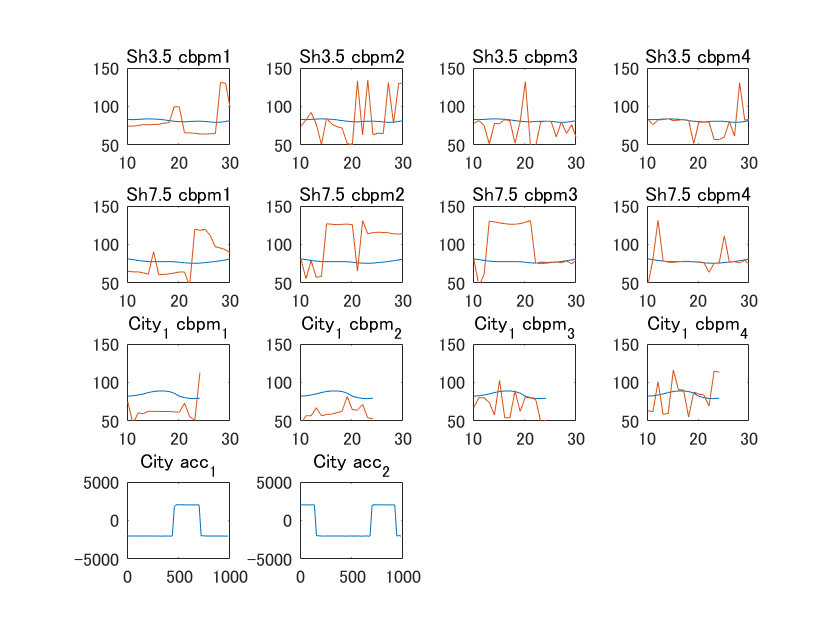


figure;
nn=0;
rows=4;cols=4;

%Plot shaker processed response data
nn=nn+1;
subplot(rows,cols,nn);
tlim=60*2;
plot(datashaker_350_2.time_sec(1:4:tlim,:),[datashaker_350_2.ppgHeartRate_Bpm(1:4:tlim,:),datashaker_350_2.candidateHeartRate_Bpm(1:4:tlim,:)])
title("Sh3.5 cbpm1")
axis([10 30 50 150])

nn=nn+1;
subplot(rows,cols,nn);
plot(datashaker_350_2.time_sec(1:4:tlim,:),[datashaker_350_2.ppgHeartRate_Bpm(1:4:tlim,:),datashaker_350_2.candidateHeartRate_Bpm(2:4:tlim,:)])
title("Sh3.5 cbpm2")
axis([10 30 50 150])

nn=nn+1;
subplot(rows,cols,nn);
plot(datashaker_350_2.time_sec(1:4:tlim,:),[datashaker_350_2.ppgHeartRate_Bpm(1:4:tlim,:),datashaker_350_2.candidateHeartRate_Bpm(3:4:tlim,:)])
title("Sh3.5 cbpm3")
axis([10 30 50 150])

nn=nn+1;
subplot(rows,cols,nn);
plot(datashaker_350_2.time_sec(1:4:tlim,:),[datashaker_350_2.ppgHeartRate_Bpm(1:4:tlim,:),datashaker_350_2.candidateHeartRate_Bpm(4:4:tlim,:)])
title("Sh3.5 cbpm4")
axis([10 30 50 150])

nn=nn+1;
subplot(rows,cols,nn);
plot(datashaker_750_2.time_sec(1:4:tlim,:),[datashaker_750_2.ppgHeartRate_Bpm(1:4:tlim,:),datashaker_750_2.candidateHeartRate_Bpm(1:4:tlim,:)])
title("Sh7.5 cbpm1")
axis([10 30 50 150])

nn=nn+1;
subplot(rows,cols,nn);
plot(datashaker_750_2.time_sec(1:4:tlim,:),[datashaker_750_2.ppgHeartRate_Bpm(1:4:tlim,:),datashaker_750_2.candidateHeartRate_Bpm(2:4:tlim,:)])
title("Sh7.5 cbpm2")
axis([10 30 50 150])

nn=nn+1;
subplot(rows,cols,nn);
plot(datashaker_750_2.time_sec(1:4:tlim,:),[datashaker_750_2.ppgHeartRate_Bpm(1:4:tlim,:),datashaker_750_2.candidateHeartRate_Bpm(3:4:tlim,:)])
title("Sh7.5 cbpm3")
axis([10 30 50 150])

nn=nn+1;
subplot(rows,cols,nn);
plot(datashaker_750_2.time_sec(1:4:tlim,:),[datashaker_750_2.ppgHeartRate_Bpm(1:4:tlim,:),datashaker_750_2.candidateHeartRate_Bpm(4:4:tlim,:)])
title("Sh7.5 cbpm4")%Plot city drive data
axis([10 30 50 150])

nn=nn+1;
subplot(rows,cols,nn);
plot(GS20_city_th99_1.time_sec(1:4:60,:),[GS20_city_th99_1.ppgHeartRate_Bpm(1:4:60,:),GS20_city_th99_1.candidateHeartRate_Bpm(1:4:60,:)])
title("City_1 cbpm_1");
axis([10 30 50 150])

nn=nn+1;
subplot(rows,cols,nn);
plot(GS20_city_th99_1.time_sec(1:4:60,:),[GS20_city_th99_1.ppgHeartRate_Bpm(1:4:60,:),GS20_city_th99_1.candidateHeartRate_Bpm(2:4:60,:)])
title("City_1 cbpm_2");
axis([10 30 50 150])


nn=nn+1;
subplot(rows,cols,nn);
plot(GS20_city_th99_1.time_sec(1:4:60,:),[GS20_city_th99_1.ppgHeartRate_Bpm(1:4:60,:),GS20_city_th99_1.candidateHeartRate_Bpm(3:4:60,:)])
title("City_1 cbpm_3");
axis([10 30 50 150])

nn=nn+1;
subplot(rows,cols,nn);
plot(GS20_city_th99_1.time_sec(1:4:60,:),[GS20_city_th99_1.ppgHeartRate_Bpm(1:4:60,:),GS20_city_th99_1.candidateHeartRate_Bpm(4:4:60,:)])
title("City_1 cbpm_4");
axis([10 30 50 150])

nn=nn+1;
subplot(rows,cols,nn);
plot(GS20_city_acc_1.Time_mS_(1:50,:),GS20_city_acc_1.ppg(1:50,:))
title("City acc_1");
% axis([10 30 -2000 2000])

nn=nn+1;
subplot(rows,cols,nn);
plot(GS20_city_acc_2.Time_mS_(1:50,:),GS20_city_acc_2.ppg(1:50,:));
title("City acc_2");
print(['heartBeatPpgData'],'-djpeg');

beat = iddata([datashaker.ppg],[datashaker.LPF1,datashaker.LPF2,datashaker.LPF3,datashaker.LPF4,datashaker.AccX_m_s2_,datashaker.AccY_m_s2_,datashaker.AccZ_m_s2_],0.02);
beat.InputName = {'LPF1';'LPF2';'LPF3';'LPF4';'AccX_m_s2_';'AccY_m_s2_';'AccZ_m_s2_'};
beat.OutputName = {'ppg'};
figure;

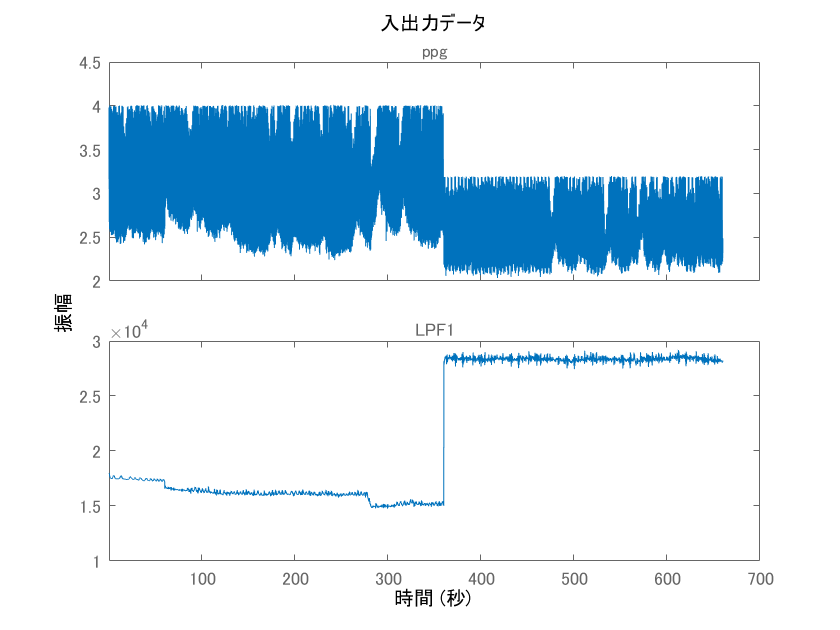

plot(beat(:,1,1))

print(['ppgLPF1Plot'],'-djpeg');

XX = beat.InputData;
YY = beat.OutputData;

% net = feedforwardnet;
% % net = configure(net,{beat.InputData', beat.OutputData'},beat.OutputData');
% view(net);

% XX1 = beat.InputData(1:300,:);
% YY1 = beat.OutputData(1:300);

% y = net(XX1')

% plot(1:100 , [y(1:100) ; YY(1:100)])

% train(net,[beat.InputData(1:300,:)]',[beat.OutputData(1:300)]')



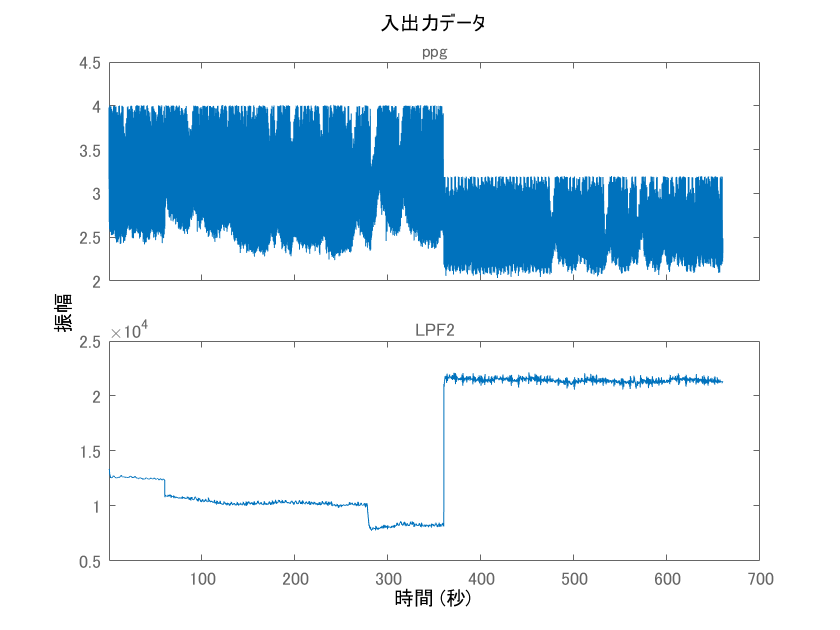

plot(beat(:,1,2))

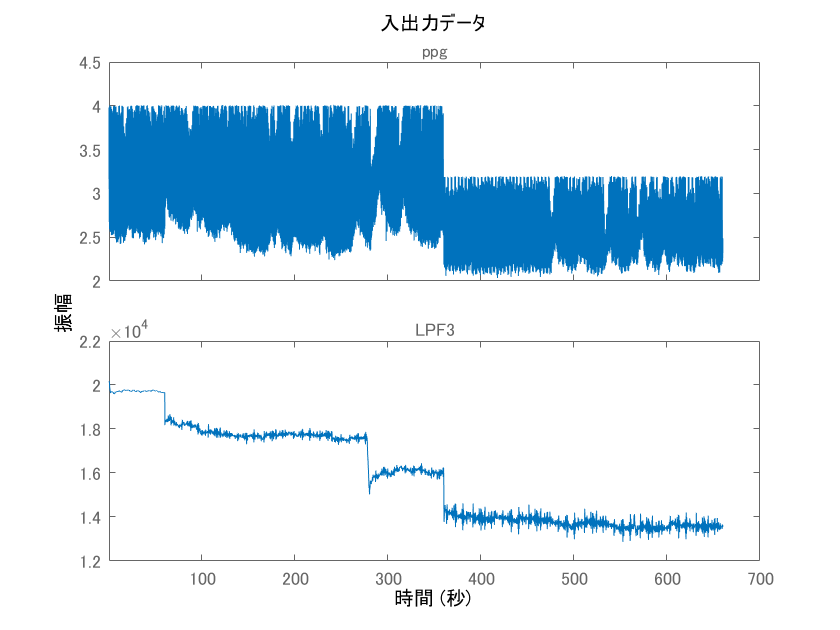

plot(beat(:,1,3))

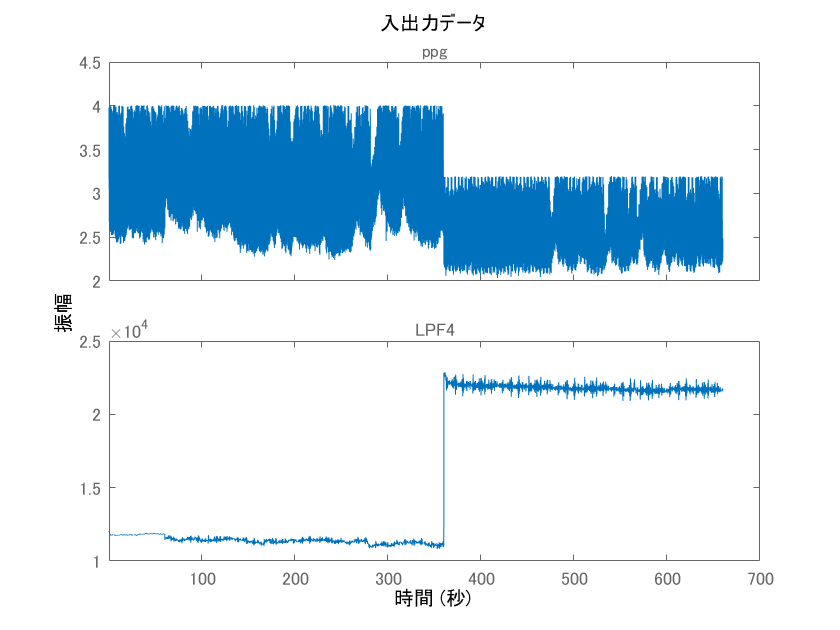

plot(beat(:,1,4))

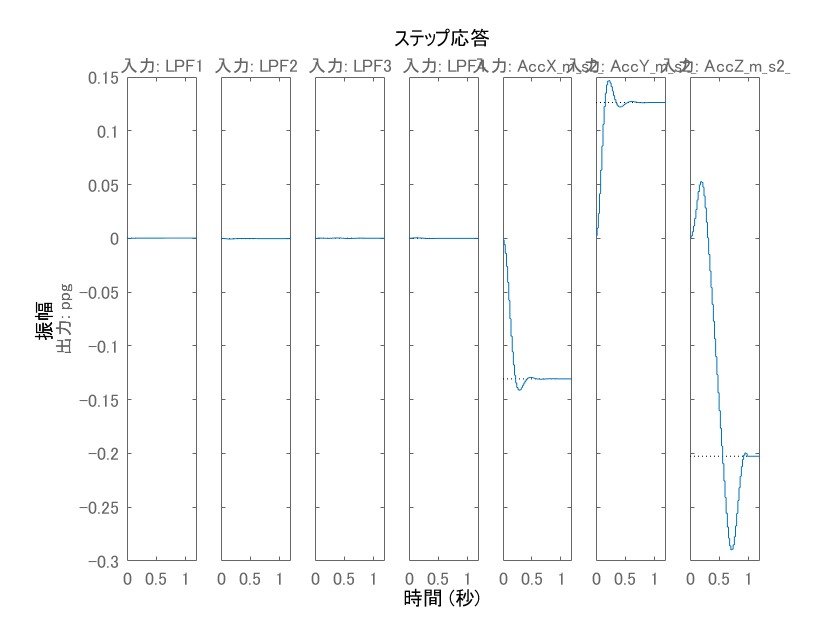

beat_mi = impulseest(beat,50);
clf, step(beat_mi)

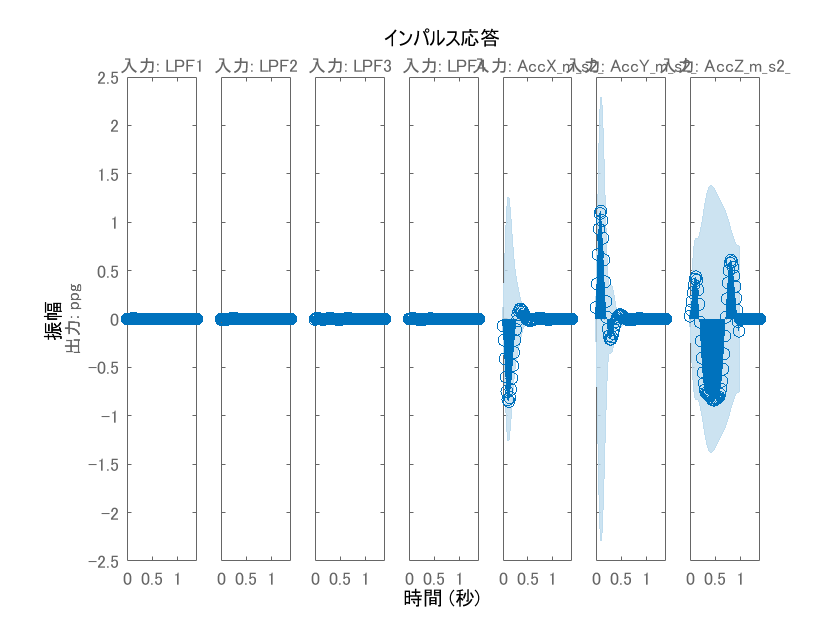

showConfidence(impulseplot(beat_mi),3)

% % Load multi-experiment data.
% load(fullfile(matlabroot,'toolbox','ident','iddemos',...
% 'data', 'twobodiesdata'));
% 
% % Create an iddata object to store the multi-experiment data.
% z1=iddata(y1,u1,0.005,'Tstart',0);
% z2=iddata(y2,u2,0.005,'Tstart',0);
% z3=iddata(y3,u3,0.005,'Tstart',0);
% Z = merge(z1,z2,z3);
% 
% % Estimate a 5th order state-space model.
% opt = n4sidOptions('Focus','simulation');
% [M,x0] = n4sid(Z,5,opt);

% X0est = x0(:,2);

% slident;

[beat_mp,x0] = ssest(beat(1:3000),6,'Ts',beat.Ts)


beat_mp =
  Discrete-time identified state-space model:
    x(t+Ts) = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
             x1        x2        x3        x4        x5        x6
   x1     0.887    0.4856    0.1373    0.2196   0.06066  -0.04922
   x2   -0.3785    0.8601    -0.188   -0.1843   -0.3474    0.2057
   x3  -0.03575   0.07687    0.9207   -0.5194   -0.1843    0.2113
   x4   -0.1269    -0.139    0.1185    0.8218   -0.6378    0.2272
   x5   0.01465   0.07451    0.1629    0.1233    0.4802    0.4541
   x6   0.01286   0.08639    0.0797   0.03281   -0.4299    0.1816
 
  B = 
             LPF1        LPF2        LPF3        LPF4  AccX_m_s2_  AccY_m_s2_  AccZ_m_s2_
   x1   0.0001663  -0.0001177   0.0004568   0.0001802    0.006503     0.04975     0.04024
   x2   0.0002757  -0.0001251   0.0009139  -0.0007841     0.06417    -0.04196     -0.1235
   x3  -3.119e-05   -0.000508     0.00126  -0.0007542     -0.1238     -0.3017     -0.1356
   x4   0.0002336   0.00046

x0 =     6.2814
  -22.5888
   -9.2819
  -18.3456
    8.0795
  -74.9185


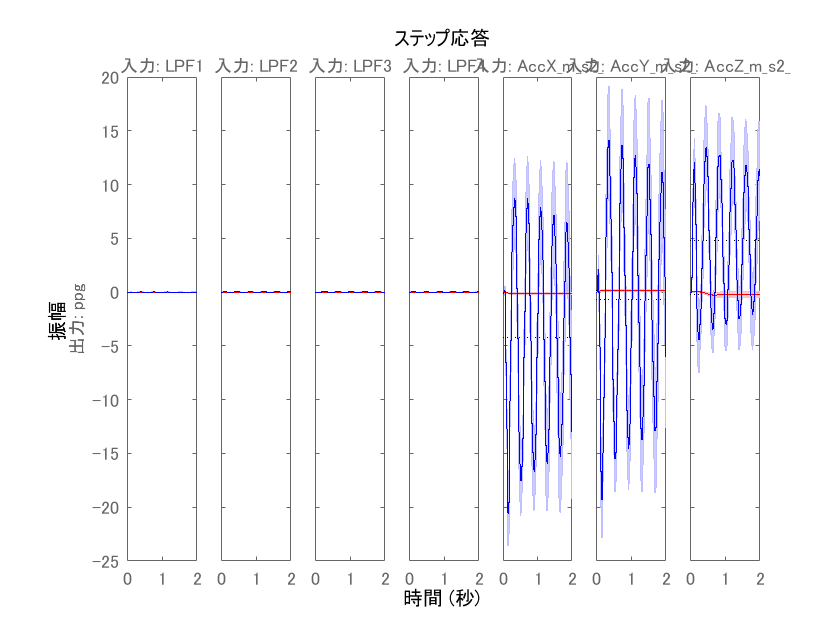

beat_h = stepplot(beat_mi,'r',beat_mp,'b',2); % Blue for direct estimate, red for mp
showConfidence(beat_h)

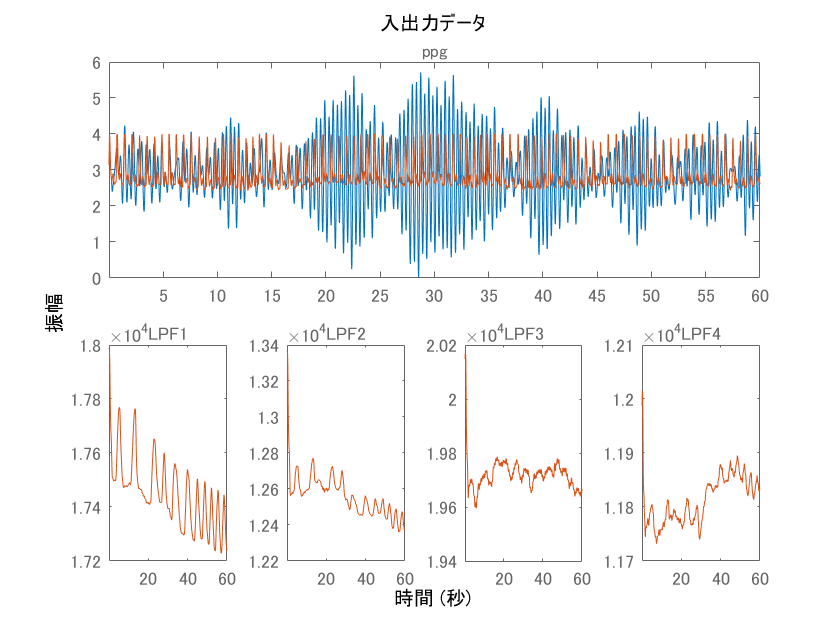

Ns=1;future = 3000; Ne=Ns+future;
y = sim(beat_mp,beat(Ns:Ne),x0);
% figure;cla;
plot( y,beat(Ns:Ne,1,1:4));

% plot(y)
% compare(beat(1:100),beat_mp)
% axis([400 420 -5 5])

simOpt = simOptions('InitialCondition',x0);
Ns=1;future=13600;Ne=Ns+future;
ysim = sim(beat_mp,beat(Ns:Ne),simOpt);

Ts=1; delta = 60; Te = Ts+delta;
Ss = Ts/0.02; Se = Te/0.02;
plot(ysim, 'b',beat(Ns:Ne),'r');
% plot(ysim(Ss:Se),'b');
[pks,locs,widths,proms] = findpeaks(ysim.OutputData(Ss:Se));
text(locs+.02,pks,num2str((1:numel(pks))'));
length(pks)/2

ans = 80

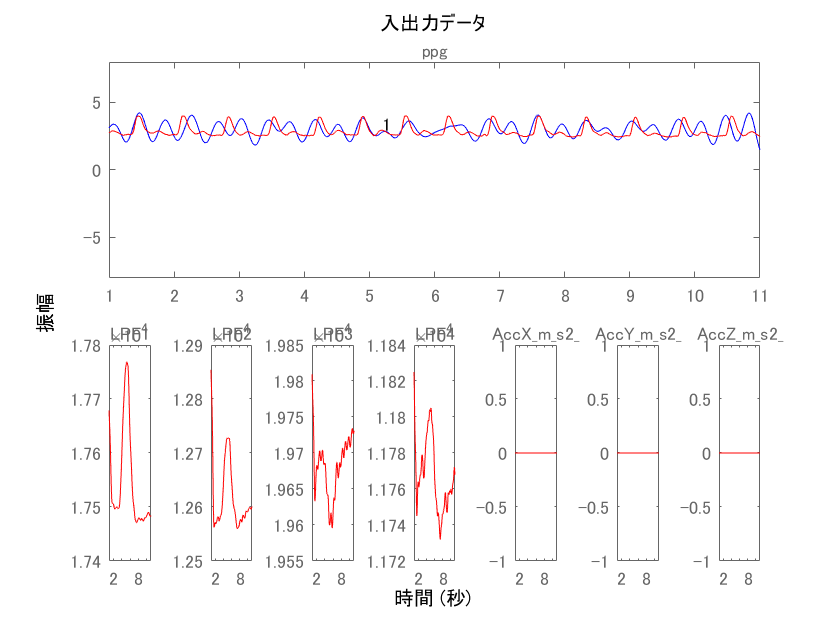

axis([Ts Te-50 -8 8])

Ts=70; delta = 60; Te = Ts+delta;
Ss = Ts/0.02; Se = Te/0.02;
plot(ysim, 'b',beat(Ns:Ne),'r');
% plot(ysim(Ss:Se),'b');
[pks,locs,widths,proms] = findpeaks(ysim.OutputData(Ss:Se));
text(locs+.02,pks,num2str((1:numel(pks))'));
length(pks)/2

ans = 80

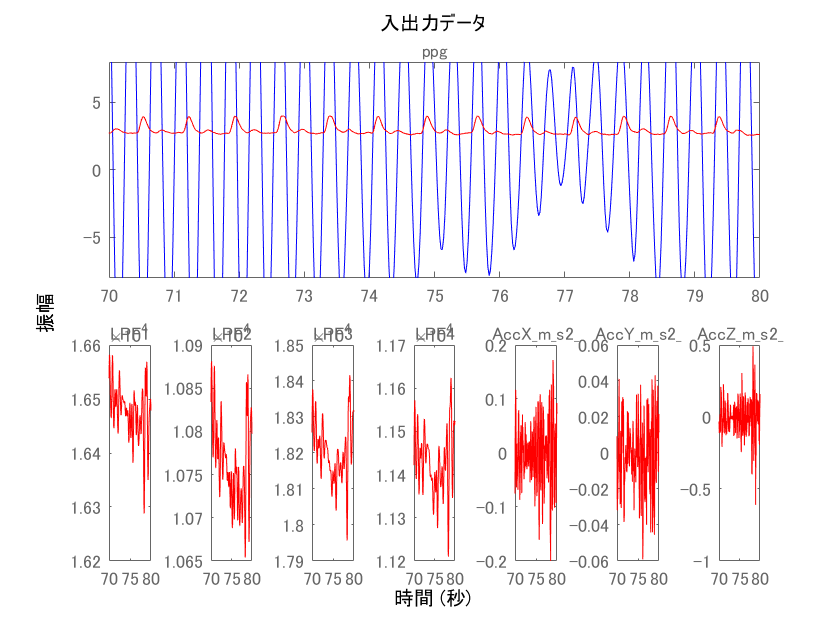

axis([Ts Te-50 -8 8])

Ts=200; delta = 60; Te = Ts+delta;
Ss = Ts/0.02; Se = Te/0.02;
plot(ysim, 'b',beat(Ns:Ne),'r');
% plot(ysim(Ss:Se),'b');
[pks,locs,widths,proms] = findpeaks(ysim.OutputData(Ss:Se));
text(locs+.02,pks,num2str((1:numel(pks))'));
length(pks)/2

ans = 81

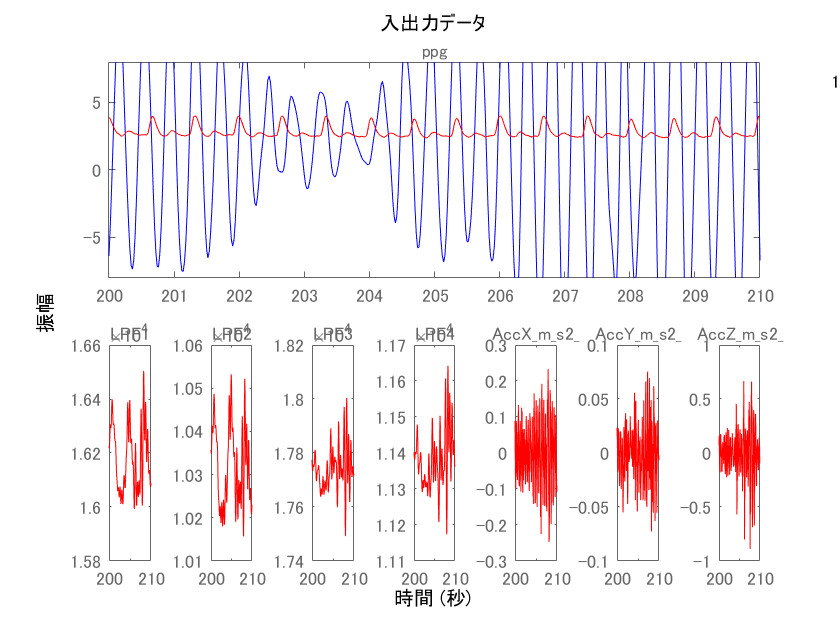

axis([Ts Te-50 -8 8])

% compare(beat(1500:1700),beat_mp,1)

% compare(beat(10000:10200),beat_mp,1);
% compare(beat(30000:30200),beat_mp,1)

## Spectral Analysis

Similarly, comparisons of the frequency response of `mp` with a spectral analysis estimate gives:

beat_msp = spa(beat);

`bode(beat_msp,beat_mp)`

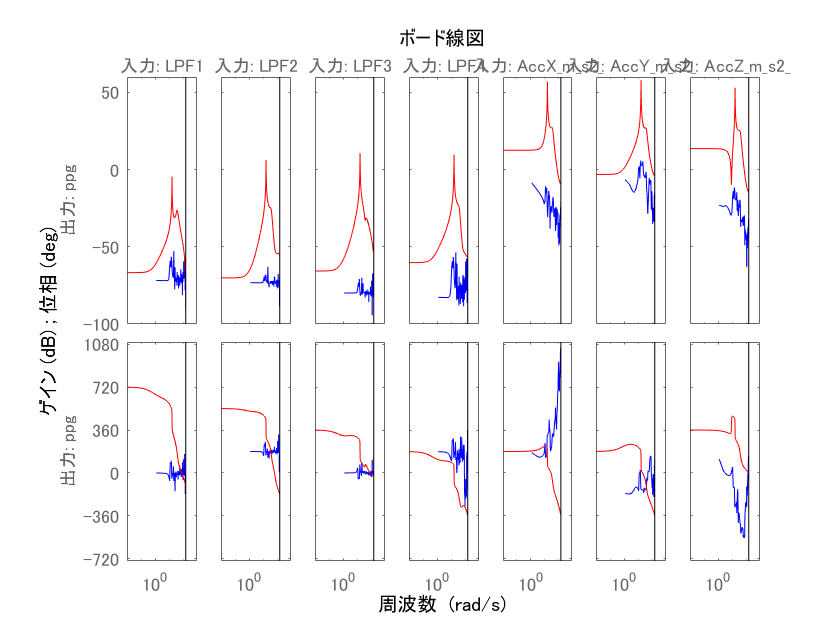

clf, bode(beat_msp,'b',beat_mp,'r')